
data_wd = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_6\log_6_wd.txt');
data_wd = fillmissing(data_wd, 'nearest');

[t_wd,u_L_wd,u_R_wd,v_L_wd,v_R_wd,T_s_wd] = get_data(data_wd);

idwd = find(u_L_wd >= 4,1,'first');
idwd = idwd + 42

idwd = 293

idd_L_wd = iddata(v_L_wd(idwd:end),u_L_wd(idwd:end),T_s_wd);
G_L_wd = tfest(idd_L_wd,2,0) 

G_L_wd =
 
  From input "u1" to output "y1":
          12.1
  ---------------------
  s^2 + 12.67 s + 42.81
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "idd_L_wd".
Fit to estimation data: 41.45%                       
FPE: 0.001048, MSE: 0.001043                         


[num, denom] = tfdata(G_L_wd); 
% Kp = 5;
num = cell2mat(num)

num =          0         0   12.0975


denom = cell2mat(denom)

denom =     1.0000   12.6687   42.8059


%simout = sim('C:\Users\Alonso\Desktop\REGBOT\Ex_8\simulink_model', 5); % simulate  for 5 seconds
%plot(simout);

%regbot_sim = sim("C:\Users\Alonso\Desktop\REGBOT\Ex_8\simulink_model", 5); % model_name is what you use for your own simulink model
%plot(regbot_sim.simout);

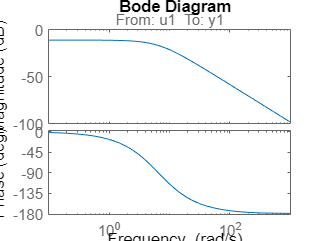

bode(G_L_wd)

## PI-Lead

w = logspace(-2,2,3000);
[mag, phase] = bode(G_L_wd,w);
Ni = 9;
alpha = 0.2;
gamma = 150;
phi_d = rad2deg(asin((1-alpha)/(1+alpha)));
phi_i = rad2deg(atan2(-1,Ni));
pc = gamma - 180 - phi_d - phi_i

pc = -65.4701

n = find(phase > pc,1,'last');
wc = w(n)

wc = 4.2548

tau_d = 1 /(sqrt(alpha)*wc)

tau_d = 0.5255

tau_i = Ni / wc

tau_i = 2.1153

Gd = tf([tau_d 1], [alpha*tau_d 1])

Gd =
 
  0.5255 s + 1
  ------------
  0.1051 s + 1
 
Continuous-time transfer function.



Gi = tf([tau_i 1],[tau_i 0])

Gi =
 
  2.115 s + 1
  -----------
    2.115 s
 
Continuous-time transfer function.



[mage, phasec] = bode(G_L_wd * Gi * Gd, wc)

mage = 0.4590

phasec = -29.9085

Kp = 1/mage %find new kp

Kp = 2.1785

%test results
figure(100)
Gol = Kp * Gi * Gd * G_L_wd

Gol =
 
  From input "u1" to output:
           29.3 s^2 + 69.6 s + 26.35
  --------------------------------------------
  0.2223 s^4 + 4.932 s^3 + 36.32 s^2 + 90.55 s
 
Continuous-time transfer function.



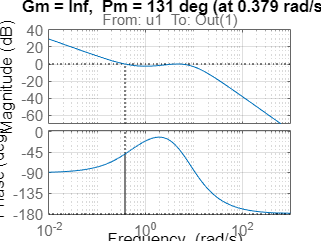

margin(Gol)
grid on

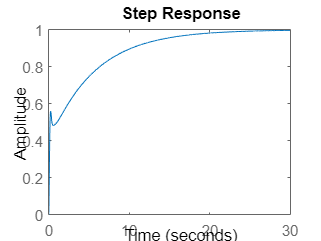

step(Gol / (1 + Gol))


[Gi_num, Gi_denom] = tfdata(Gi)

Gi_num = 1×1 cell array
    {[2.1153 1]}


Gi_denom = 1×1 cell array
    {[2.1153 0]}


Gi_num = cell2mat(Gi_num)

Gi_num =     2.1153    1.0000


Gi_denom = cell2mat(Gi_denom)

Gi_denom =     2.1153         0



[Gd_num, Gd_denom] = tfdata(Gd)

Gd_num = 1×1 cell array
    {[0.5255 1]}


Gd_denom = 1×1 cell array
    {[0.1051 1]}


Gd_num = cell2mat(Gd_num)

Gd_num =     0.5255    1.0000


Gd_denom = cell2mat(Gd_denom)

Gd_denom =     0.1051    1.0000



simout = sim('C:\Users\Alonso\Desktop\REGBOT\Ex_8\simulink_model', 50); % simulate  for 5 seconds
plot(simout);

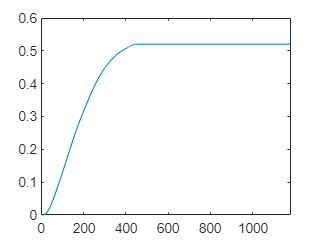

test_wu = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_8\log_8_wu_nos_4.txt');
test_wu = fillmissing(test_wu, 'nearest');
test_wd = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_8\log_8_wd_nos_4.txt');
test_wd = fillmissing(test_wd, 'nearest');

x_wu = table2array(test_wu(:,6));
x_wd = table2array(test_wd(:,6));

plot(x_wd)

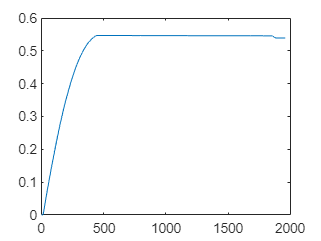

plot(x_wu)

function [t,u_L,u_R,v_L,v_R,T_s] = get_data(data)
    t = table2array(data(:,1));     % time stamps
    u_L = table2array(data(:,2));   % left motor voltage
    u_R = table2array(data(:,3));   % right motor voltage
    v_L = table2array(data(:,4));  % left motor velocity 
    v_R = table2array(data(:,5));  % right motor velocity
    T_s = t(2) - t(1);              % compute sampling time
end

